# Homework #3

Author: Victoria Subritzky Katz

Date: 09/11/2023

## Q1 

num_released = 0:1:10;  %possible values for the total number of quanta released
num_quanta = 10;        %total number of available quanta
release_prob = .2;      %release probability for a single quanta
prob_binomial = binopdf(num_released,num_quanta,release_prob); %bionomial probability function

temp = [num_released;prob_binomial];
fprintf('Probability (Column 2) of that number of quanta (Cloumn 1) being released\n')

Probability (Column 2) of that number of quanta (Cloumn 1) being released


fprintf('%5g %5g\n',temp)

    0 0.107374
    1 0.268435
    2 0.30199
    3 0.201327
    4 0.0880804
    5 0.0264241
    6 0.00550502
    7 0.000786432
    8 7.3728e-05
    9 4.096e-06
   10 1.024e-07


## Q2

num_quanta = 14;            %number of available quanta
release_prob = .1:.1:1;     %possible values for the release probability for a single quanta, 0-1 incremented by .1
num_released = 8;           %number of quanta released

prob_binomial = binopdf(num_released,num_quanta,release_prob);  %binomial probability given above params across possible release probabilities

temp = [release_prob;prob_binomial]; %temp structure for printing as a table
fprintf('Probability (column 2) of that 8 quanta were released given the release probability in column 1\n')

Probability (column 2) of that 8 quanta were released given the release probability in column 1


fprintf('%5g %5g\n',temp)

  0.1 1.59592e-05
  0.2 0.00201528
  0.3 0.02318
  0.4 0.0918212
  0.5 0.183289
  0.6 0.206598
  0.7 0.126202
  0.8 0.0322445
  0.9 0.00129269
    1     0


The release probability most likely to result in the release of 8 quanta given their are 14 available is 0.6, this is evidenced in the data above where it results in the highest liklihood of 8 quanta being released (0.207). 

## Q3

%Liklihood estimations for a release probability of 0.1 across two
%measurements
num_quanta = 14;            %number of available quanta
release_prob = .1;          %value of teh release probability
num_released1 = 8;          %number of quanta released for measurement 1
num_released2 = 5;          %number of quanta released for measurement 2

prob_binomial_1 = binopdf(num_released1,num_quanta,release_prob); %binomial probability for measurement 1 across possible release probabilities
prob_binomial_2 = binopdf(num_released2,num_quanta,release_prob); %binomial probability for measurement 2 across possible release probabilities

prob_binomial_comb_01 = prob_binomial_1*prob_binomial_2; %combining the two independent measurements by multiplication

logll_prob_binomial_01 = log(prob_binomial_1)+ log(prob_binomial_2); 
fprintf('The total liklihood across the two samples for a release probability of 0.1 is %1.10f',prob_binomial_comb_01)

The total liklihood across the two samples for a release probability of 0.1 is 0.0000001238

fprintf('The total log-liklihood across the two samples for a release probability of 0.1 is %1.10f',logll_prob_binomial_01)

The total log-liklihood across the two samples for a release probability of 0.1 is -15.9047449159

%Liklihood estimation across release probabilities range 0-1 with .1
%increment for 2 measurements
num_quanta = 14;            %number of available quanta
release_prob = 0:.1:1;     %possible values for the release probability for a single quanta, 0-1 incremented by .1
num_released1 = 8;          %number of quanta released for measurement 1
num_released2 = 5;          %number of quanta released for measurement 2

prob_binomial_1 = binopdf(num_released1,num_quanta,release_prob); %binomial probability for measurement 1 across possible release probabilities
prob_binomial_2 = binopdf(num_released2,num_quanta,release_prob); %binomial probability for measurement 2 across possible release probabilities

prob_binomial_comb = prob_binomial_1.*prob_binomial_2; %combining the two independent measurements by multiplication

temp = [release_prob;prob_binomial_comb];
fprintf('The liklihood (column 2) of each release probability (column 1) for two samples')

The liklihood (column 2) of each release probability (column 1) for two samples

fprintf('%5g %5g\n',temp)

    0     0
  0.1 1.23782e-07
  0.2 0.000173284
  0.3 0.00455058
  0.4 0.01897
  0.5 0.0223965
  0.6 0.00843113
  0.7 0.00083582
  0.8 1.08303e-05
  0.9 1.52817e-09
    1     0


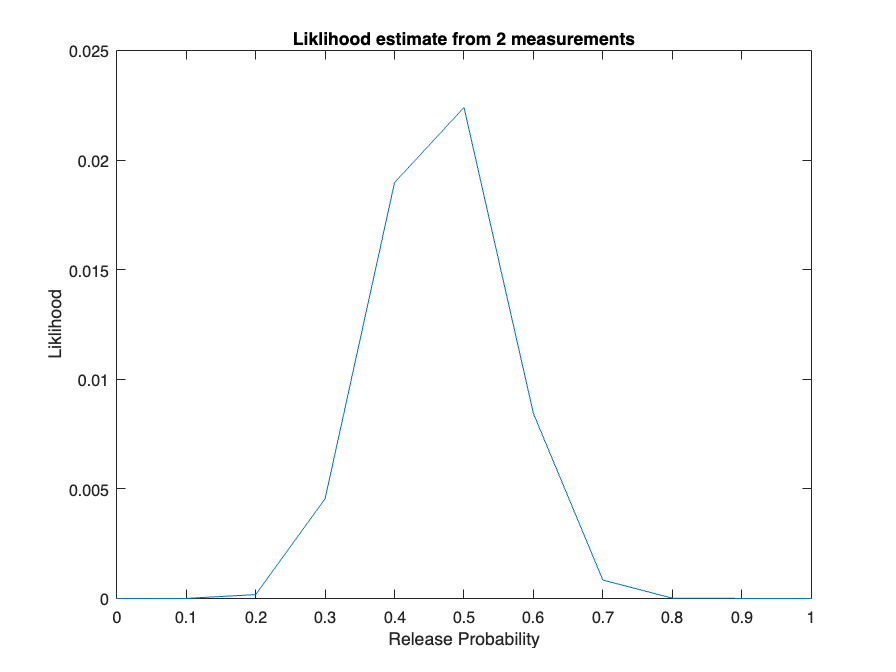

%plotting the release probability against the liklihood value determined
%through the binomial pdf across two measurements
plot(release_prob,prob_binomial_comb)
title('Liklihood estimate from 2 measurements')
ylabel('Liklihood')
xlabel('Release Probability')

logll_prob_binomial = log(prob_binomial_1)+ log(prob_binomial_2); %calculating the log-liklihood across the two measurements
temp = [release_prob;logll_prob_binomial];
fprintf('The log-liklihood (column 2) of each release probability (column 1) for two samples')

The log-liklihood (column 2) of each release probability (column 1) for two samples

fprintf('%5g %5g\n',temp)

    0  -Inf
  0.1 -15.9047
  0.2 -8.66058
  0.3 -5.3925
  0.4 -3.96489
  0.5 -3.79885
  0.6 -4.77583
  0.7 -7.0871
  0.8 -11.4332
  0.9 -20.2992
    1  -Inf


[estimate,index] = max(prob_binomial_comb); %determine the highest value and its index in the liklihood spread
fprintf("The maximum liklihood value across a 0-1 range of possible release values at .1 increments is %1.5f",estimate)

The maximum liklihood value across a 0-1 range of possible release values at .1 increments is 0.02240

release_prob_estimate = release_prob(index); %extract the release probability value corresponding to that number
fprintf("The most likely value for the probability of release is %.2f across two measurements", release_prob_estimate)

The most likely value for the probability of release is 0.50 across two measurements


%Liklihood estimation across release probabilities range 0-1 with .01
%increment for 2 measurements
num_quanta = 14;            %number of quanta available
release_prob = 0:.01:1;     %possible release probability values, increased resolution to .01 in range 0-1
num_released1 = 8;          %number of quanta released for measurement 1
num_released2 = 5;          %number of quanta released for measurement 2

prob_binomial_1 = binopdf(num_released1,num_quanta,release_prob); %binomial probability for measurement 1 across possible release probabilities
prob_binomial_2 = binopdf(num_released2,num_quanta,release_prob); %binomial probability for measurement 2 across possible release probabilities

prob_binomial_comb = prob_binomial_1.*prob_binomial_2; %combining the two independent measurements by multiplication

[estimate,index] = max(prob_binomial_comb); %determine the highest value and its index in the liklihood spread
fprintf("The maximum liklihood value across a 0-1 range of possible release values at .01 increments is %1.5f",estimate)

The maximum liklihood value across a 0-1 range of possible release values at .01 increments is 0.02403

release_prob_estimate = release_prob(index); %extract the release probability value corresponding to that number
fprintf("The most likely value for the probability of release is %.2f across two measurements", release_prob_estimate)

The most likely value for the probability of release is 0.46 across two measurements

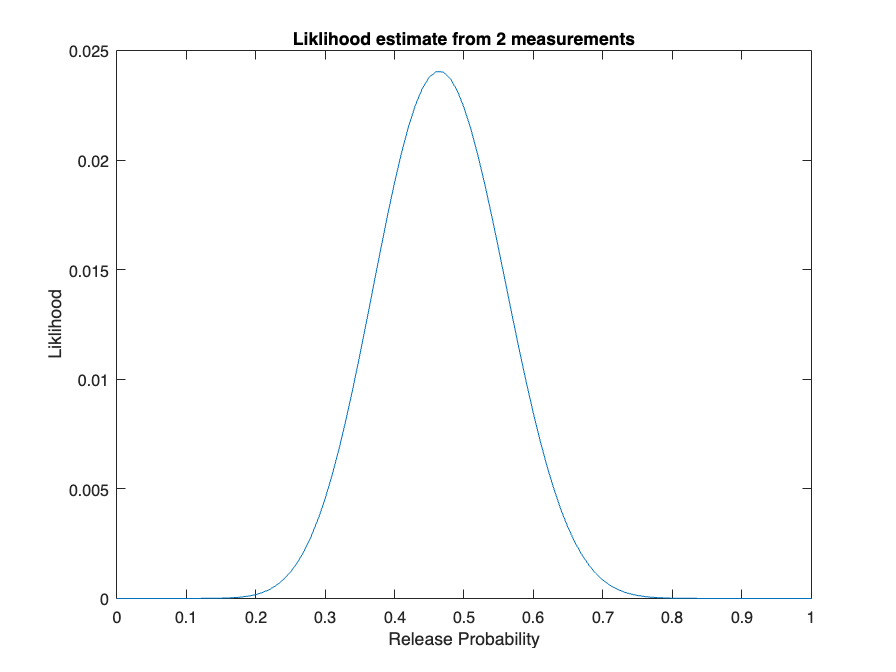



%plotting the release probability against the liklihood value determined
%through the binomial pdf across two measurements
plot(release_prob,prob_binomial_comb)
title('Liklihood estimate from 2 measurements')
ylabel('Liklihood')
xlabel('Release Probability')

logll_prob_binomial = log(prob_binomial_1)+ log(prob_binomial_2); %calculating the log-liklihood across the two measurements


Assuming the release probability is 0.1, the total liklihood estimation across the two measurements is 0.0000001238 and the the log-liklihood estimation is -15.9047. 

The liklihood estimate of the release probability across a range from 0-1 of possible probabilities incremented by 0.1,  is 0.5. However, when the resolution is improved by decreasing that increment to 0.01, the estimate improves is specifity to 0.46. Increasing the sample size of the possible values for the release probability by upping the resolution to 0.01, improved the estimated value. This improvement is also evidenced in the increased smoothness of the graph of the liklihood estimates across release probabilities. 

## Q4

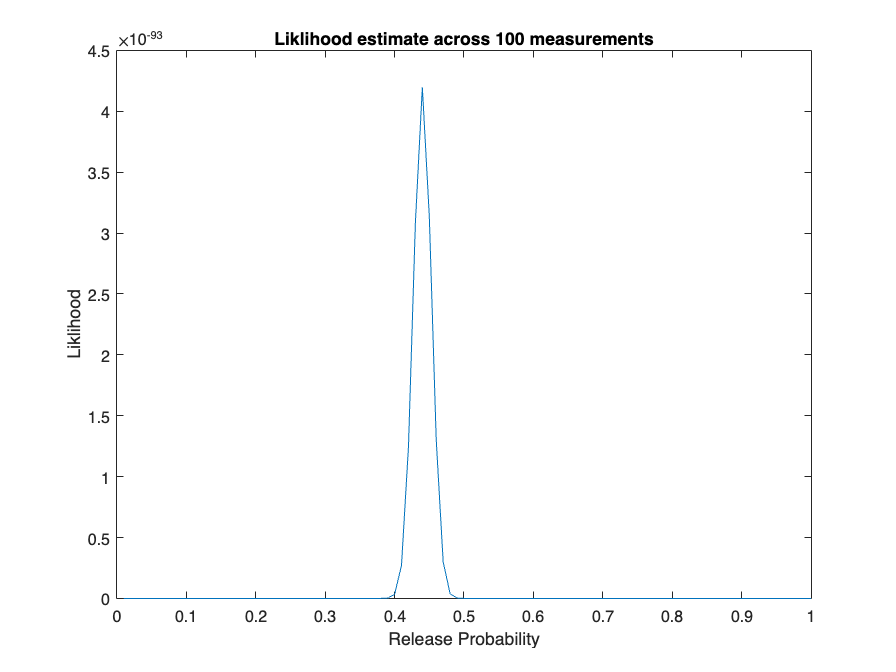

num_quanta = 14;                        %number of quanta available
release_prob = .01:.01:1;               %possible release probability values, range 0-1 at .01 increments
num_released = 2:1:10;                  %range of observed numbers of quanta released
weighting = [3,5,10,19,26,16,16,5,5];   %the counts of how many times each release number was observed
prob_binomial_tot = [];                 %declaring empty struct for the binomial pdf across the range
                                        % across the range of quanta released and the range of
                                        % possible release probabilities
%loop through observed number of quantas released
for i = 1:length(num_released)
    prob_binomial_tot(i,:) = binopdf(num_released(i),num_quanta,release_prob); %calculate the binomial pdf across possible release values for that number of quanta released
    %each column is a different release prob, each row is a different
    %number of quanta released
end

%weight the binomial probability by the frequency of a given number of
%quanta being released. Do this by raising it to the power of the count
weighted_prob = prob_binomial_tot'.^weighting;

%combine the independent measures by multiplying
% %dumb way to multiply across columns along row
for i = 1:length(weighted_prob(:,1))
    row_cur = weighted_prob(i,:);
    liklihood(i) = prod(row_cur, "all" );
end


%plot results
plot(release_prob,liklihood)
title('Liklihood estimate across 100 measurements')
ylabel('Liklihood')
xlabel('Release Probability')

[estimate,index] = max(liklihood); %determine the highest value and its index in the liklihood spread
fprintf("The maximum liklihood value across a 0-1 range of possible release values at .01 increments for 100 measurements is %1.100f",estimate)

The maximum liklihood value across a 0-1 range of possible release values at .01 increments for 100 measurements is 0.0000000000000000000000000000000000000000000000000000000000000000000000000000000000000000000041974772

release_prob_estimate = release_prob(index); %extract the release probability value corresponding to that number
fprintf("The most likely value for the probability of release is %.2f", release_prob_estimate)

The most likely value for the probability of release is 0.44

## Q5

Let's say that you have run an exhaustive set of experiments on this synapse and have determined that the true release probability is 0.3 (within some very small tolerance). Now you want to test whether changing the temperature of the preparation affects the release probability. So you change the temperature, perform the experiment, and measure 7 quantal events for the same 14 available quanta. Compute p hat. Standard statistical inference now asks the question, what is the probability that you would have obtained that measurement given a Null Hypothesis of no effect? In this case, no effect corresponds to an unchanged value of the true release probability (i.e., its value remained at 0.3 even with the temperature change). What is the probability that you would have gotten that measurement if your Null Hypothesis were true? Can you conclude that temperature had an effect?

True release prob = .3

at new temp observed 7 quanta from the 7

- compute p hat

- what is the probability that you would have obtained that measurement given a Null Hypothesis of no effect? 

- What is the probability that you would have gotten that measurement if your Null Hypothesis were true? 

- Can you conclude that temperature had an effect?

(obersved-mean)^2/(standard deviation)

.5-.3

standard deviation = sum

num_released = 7;  %number of quanta released
num_quanta = 14;        %total number of available quanta
release_prob = 0:.01:1;     %possible values for the release probability for a single quanta, 0-1 incremented by .1

prob_binomial = binopdf(num_released,num_quanta,release_prob); %bionomial probability function

[estimate,index] = max(prob_binomial); %determine the highest value and its index in the liklihood spread
fprintf("The maximum liklihood value across a 0-1 range of possible release values at .01 increments is %1.5f",estimate)

The maximum liklihood value across a 0-1 range of possible release values at .01 increments is 0.20947

release_prob_estimate = release_prob(index); %extract the release probability value corresponding to that number
fprintf("The most likely value for the probability of release is %.2f", release_prob_estimate)

The most likely value for the probability of release is 0.50

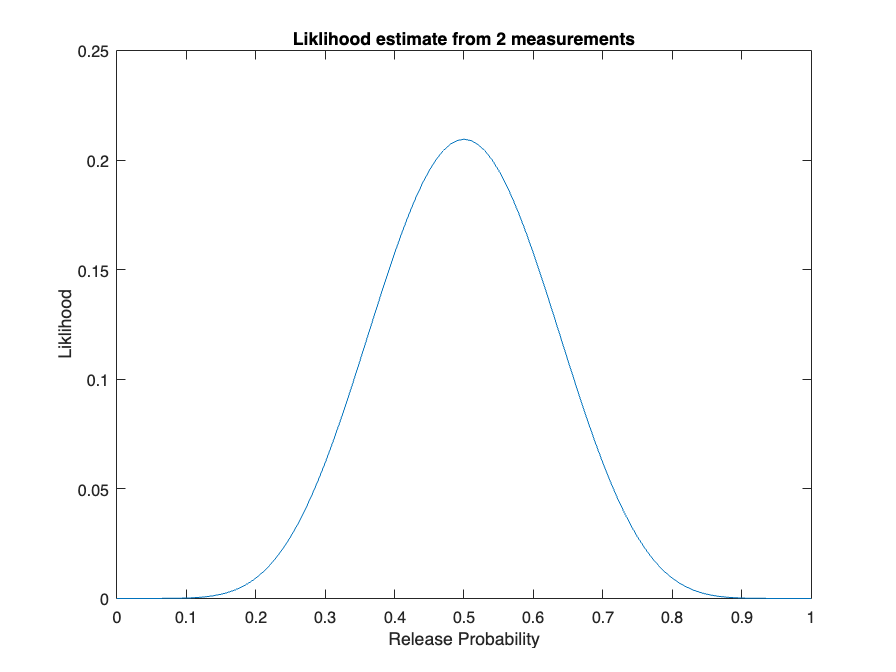


%plotting the release probability against the liklihood value determined
%through the binomial pdf across two measurements
plot(release_prob,prob_binomial)
title('Liklihood estimate from 2 measurements')
ylabel('Liklihood')
xlabel('Release Probability')

known_release_prob = .3;
std = sqrt((release_prob_estimate-known_release_prob)^2/1);
z_score = (release_prob_estimate-known_release_prob)/std; 

Given a z_score value of 1, using a standard z-score table you can determine the probability of obtaining the measurement of 7 quanta given a Null Hypothesis of no effect to be 0.317 and the probability of obtaining the 7 quanta measurement given the Null Hypothesis were true of 0.683. Thus, we cannot conclude that the temperature had an efefct from this single sample, as the probability is not below any standard confidence interval. 